# Lab2 fishing

% Determine an optimal fishing zone and speed
% Maximise profits, minimise Risk and Polution
clear
close all


## Parameters

x=50:50:1400

x =           50         100         150         200         250         300         350         400         450         500         550         600         650         700         750         800         850         900         950        1000        1050        1100        1150        1200        1250        1300        1350        1400


v=25:25:500

v =     25    50    75   100   125   150   175   200   225   250   275   300   325   350   375   400   425   450   475   500


k=1;
b=0.25*10^(-4);

Profit=(15-2.*x'./v).*x'-b*x'.*v.^2

Profit = 	1.0e+05 *

    0.0055    0.0065    0.0068    0.0069    0.0069    0.0069    0.0068    0.0067    0.0066    0.0065    0.0064    0.0062    0.0060    0.0058    0.0056    0.0054    0.0051    0.0049    0.0046    0.0043
    0.0070    0.0109    0.0122    0.0127    0.0130    0.0131    0.0131    0.0130    0.0128    0.0126    0.0124    0.0121    0.0117    0.0114    0.0110    0.0105    0.0100    0.0095    0.0089    0.0083
    0.0045    0.0134    0.0163    0.0176    0.0183    0.0187    0.0188    0.0187    0.0186    0.0184    0.0180    0.0176    0.0172    0.0166    0.0160    0.0154    0.0147    0.0139    0.0131    0.0122
   -0.0020    0.0139    0.0191    0.0215    0.0228    0.0235    0.0239    0.0240    0.0239    0.0237    0.0233    0.0228    0.0223    0.0216    0.0208    0.0200    0.0191    0.0181    0.0170    0.0159
   -0.0125    0.0123    0.0205    0.0244    0.0265    0.0278    0.0284    0.0288    0.0288    0.0286    0.0282    0.0277    0.0271    0.0263    0.0254    0.0244    0.0233    0

Risk=k*x.*ones(length(v),1)

Risk =           50         100         150         200         250         300         350         400         450         500         550         600         650         700         750         800         850         900         950        1000        1050        1100        1150        1200        1250        1300        1350        1400
          50         100         150         200         250         300         350         400         450         500         550         600         650         700         750         800         850         900         950        1000        1050        1100        1150        1200        1250        1300        1350        1400
          50         100         150         200         250         300         350         400         450         500         550         600         650         700         750         800         850         900         950        1000        1050        1100        1150        1200        1250        1300       

Pollution=x'.*v.^2

Pollution =        31250      125000      281250      500000      781250     1125000     1531250     2000000     2531250     3125000     3781250     4500000     5281250     6125000     7031250     8000000     9031250    10125000    11281250    12500000
       62500      250000      562500     1000000     1562500     2250000     3062500     4000000     5062500     6250000     7562500     9000000    10562500    12250000    14062500    16000000    18062500    20250000    22562500    25000000
       93750      375000      843750     1500000     2343750     3375000     4593750     6000000     7593750     9375000    11343750    13500000    15843750    18375000    21093750    24000000    27093750    30375000    33843750    37500000
      125000      500000     1125000     2000000     3125000     4500000     6125000     8000000    10125000    12500000    15125000    18000000    21125000    24500000    28125000    32000000    36125000    40500000    45125000    50000000
      156250      625000

## Q2 and Q4

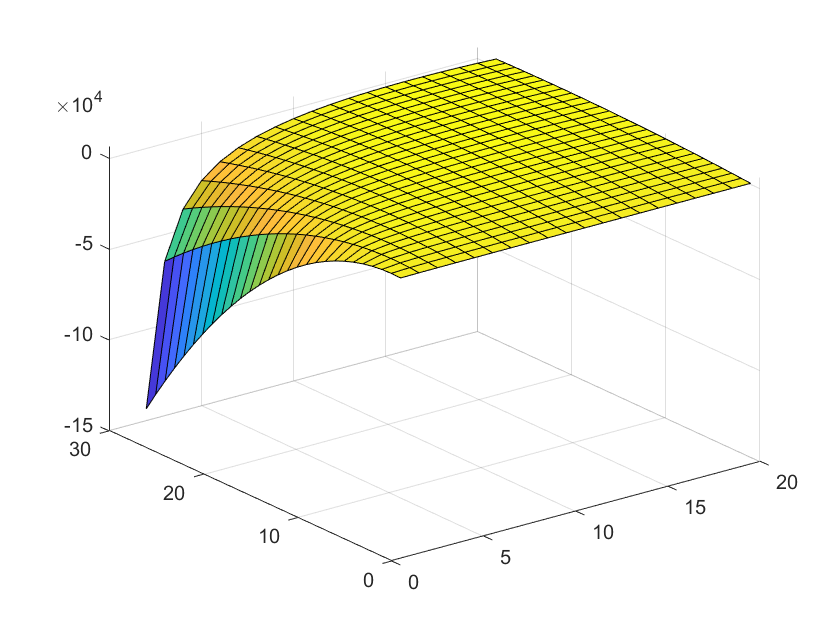

%make a graphe of profit


figure(1)
hold on
pcolor(v,x,Profit)
title('Profit')
xlabel('Distance')
ylabel('Speed')
caxis([0 7000]) %set limits on color scale

%Plot a red circle at the maximum Profit (Q1)
[a b] = find(Profit==max(max(Profit)))

a = 21

b = 14

figure(1)
plot(v(b),x(a),'ro')
%% f

% Q2 jcol contains 28 values of row indexed
% maxval contains 28 values of Profit
[malVal jcol]=max(Profit,[],2) %max in row

malVal = 	1.0e+03 *

    0.6905
    1.3104
    1.8780
    2.4000
    2.8780
    3.3203
    3.7231
    4.0950
    4.4269
    4.7365


jcol =      5
     6
     7
     8
     9
     9
    10
    10
    10
    11



% plot these points using magenta stars
figure(1)
plot(v(jcol),x,'m*')

% Q4
[maxVal irow]=max(Profit)

maxVal = 	1.0e+03 *

    0.6984    1.3875    2.0578    2.7125    3.3342    3.9073    4.4263    4.9000    5.3008    5.6419    5.9075    6.0958    6.2055    6.2344    6.1795    6.0500    5.8387    5.5535    5.2006    4.7850


irow =      2     4     6     7     9    11    12    14    15    17    18    19    20    21    22    22    22    22    22    22


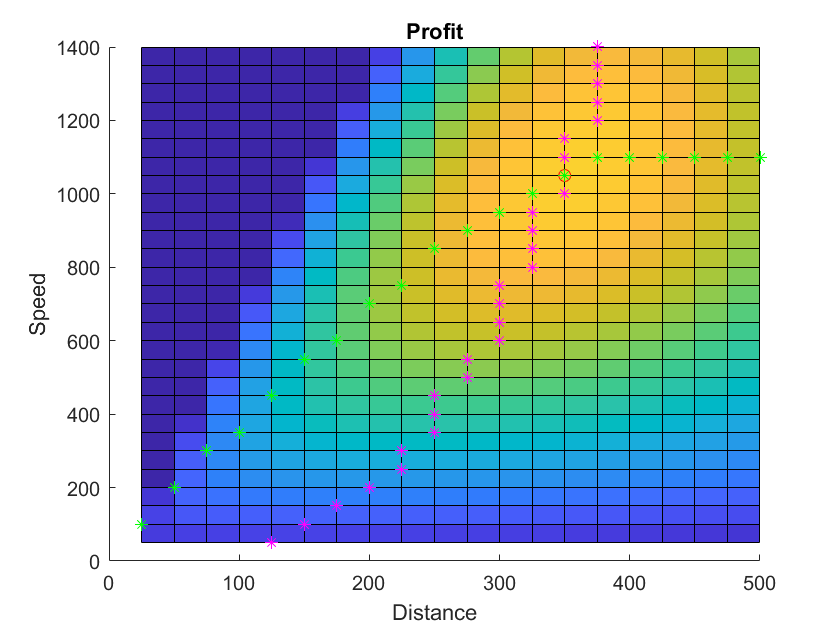

figure(1)
plot(v,x(irow),'g*')

## Q5 Pareto of Profit and Pollution

## Using a series o weighted sum to determine the Pareto optimal set of solutions

%Step1 normalise/scale the objective functions
ProfitScale= (Profit-min(min(Profit)))/(max(max(Profit))-min(min(Profit)))

ProfitScale =     0.9600    0.9607    0.9609    0.9610    0.9610    0.9610    0.9609    0.9609    0.9608    0.9607    0.9606    0.9605    0.9604    0.9602    0.9601    0.9599    0.9597    0.9595    0.9593    0.9591
    0.9610    0.9638    0.9647    0.9651    0.9653    0.9653    0.9653    0.9653    0.9652    0.9650    0.9648    0.9646    0.9644    0.9641    0.9638    0.9635    0.9632    0.9628    0.9624    0.9620
    0.9593    0.9656    0.9676    0.9685    0.9690    0.9692    0.9693    0.9693    0.9692    0.9690    0.9688    0.9685    0.9682    0.9678    0.9674    0.9669    0.9664    0.9659    0.9653    0.9647
    0.9547    0.9659    0.9695    0.9712    0.9722    0.9727    0.9729    0.9730    0.9729    0.9728    0.9725    0.9722    0.9718    0.9713    0.9708    0.9702    0.9695    0.9689    0.9681    0.9673
    0.9473    0.9648    0.9705    0.9733    0.9748    0.9757    0.9761    0.9764    0.9764    0.9762    0.9760    0.9756    0.9752    0.9746    0.9740    0.9733    0.9725    0.9716  

PollutionScale=(Pollution-min(min(Pollution)))/(max(max(Pollution))-min(min(Pollution)))

PollutionScale =          0    0.0003    0.0007    0.0013    0.0021    0.0031    0.0043    0.0056    0.0071    0.0088    0.0107    0.0128    0.0150    0.0174    0.0200    0.0228    0.0257    0.0288    0.0321    0.0356
    0.0001    0.0006    0.0015    0.0028    0.0044    0.0063    0.0087    0.0113    0.0144    0.0178    0.0215    0.0256    0.0301    0.0349    0.0401    0.0456    0.0515    0.0578    0.0644    0.0713
    0.0002    0.0010    0.0023    0.0042    0.0066    0.0096    0.0130    0.0171    0.0216    0.0267    0.0323    0.0385    0.0452    0.0524    0.0602    0.0685    0.0773    0.0867    0.0966    0.1071
    0.0003    0.0013    0.0031    0.0056    0.0088    0.0128    0.0174    0.0228    0.0288    0.0356    0.0431    0.0513    0.0603    0.0699    0.0803    0.0913    0.1031    0.1156    0.1289    0.1428
    0.0004    0.0017    0.0039    0.0071    0.0111    0.0160    0.0218    0.0285    0.0361    0.0446    0.0539    0.0642    0.0754    0.0874    0.1004    0.1142    0.1289    0.144

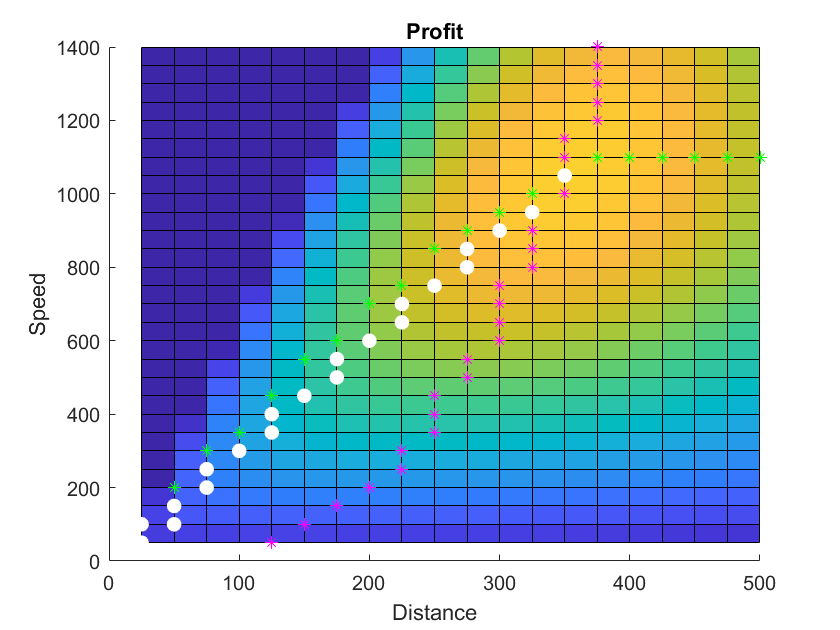



%Step2 choose values for weights (lambda)
for lam=0:0.01:1

    %Step3 build a weighted sum 
    WS=lam*ProfitScale+(1-lam)*(1-PollutionScale);
    
    %Step4 locate the optimal solution for each weighted sum
    [a b]=find(WS==max(max(WS)));
    
    figure(1) %add to figure 1 with large white dot
    plot(v(b),x(a),'w.','MarkerSize',25)

end